 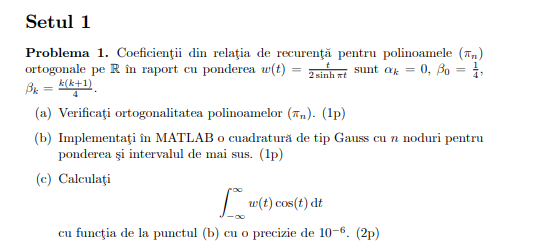

clear;
close all;
clc;

%b)
n=5;

$\alpha_k$vor fi urmatoarele (pentru n=5):

alpha_k=zeros(1, 5)

$\beta_k$vor fi urmatoarele (pentru n=5):

k = (1:5);
beta_k=(k.*(k + 1))/4
beta_k=[1/4,beta_k]

Noduriile si coeficientii cuadraturii vor fi:

[noduri,coeficienti]=Gaussquad(alpha_k,beta_k)

%c)
syms t
valoare_integrala_matlab=vpa(int(t/(2*sinh(pi*t))*cos(t),t,sym(-Inf),sym(Inf)))

format longg
f=@(x) cos(x);
eroare=1e-6;
ultima_valoare_calculata=0;
for n=5:50
    alpha_k=zeros(1, n);
    k = (1:n-1);
    beta_k=(k.*(k + 1))/4;
    beta_k=[1/4,beta_k];
    [noduri,coeficienti]=Gaussquad(alpha_k,beta_k);
    valoare_functie=vquad(noduri,coeficienti,f);
    if abs(valoare_functie-ultima_valoare_calculata) < eroare
        fprintf('Valoarea integralei este %2d', valoare_functie);
        fprintf('Convergenta obtinuta pentru %d noduri', n);
        break;
    end
    ultima_valoare_calculata=valoare_functie;
end

function [g_nodes,g_coeff]=Gaussquad(alpha,beta)
%GAUSSQUAD - generate Gaussian quadrature formula
%computes nodes and coefficients for 
%Gauss rules given alpha and beta
%method - Jacobi matrix
n=length(alpha); rb=sqrt(beta(2:n));
J=diag(alpha)+diag(rb,-1)+diag(rb,1);
[v,d]=eig(J);
g_nodes=diag(d); 
g_coeff=beta(1)*v(1,:).^2;
end

function I=vquad(g_nodes,g_coeff,f)
I=g_coeff*f(g_nodes);
end
